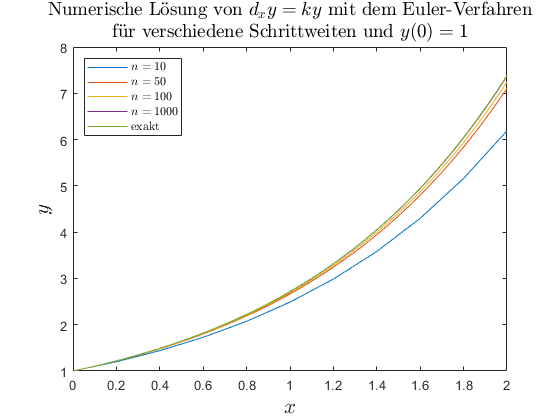

clear;
% Numerische Lösung von y* = k*y mit Eulerverfahren
% Setup
k = 1;          % Wachstums-/Zerfallskonstante
x_0 = 0;        % Stelle des Anfangswerts = linke Intervallgrenze
y_0 = 1;        % Anfangswert
x_max = 2;      % Rechte Intervallgrenze

f = @(y) k.*y ;         % Rechte Seite der DGL y' = k*y
sol = @(x) exp(k.*x);   % Exakte Lösung
n = [10 50 100 1000];   % Zahl der Raumpunkte nach Diskretisierung

% Iteration und Plot für gegebene n
for j = 1:length(n)
    [a,b] = fwdEuler(f, n(j), x_max/n(j), y_0, x_0, x_max);
    plot(a, b)
    hold on
end

% Plot der exakten Lösung
plot(a, sol(a))
hold off;
title({'Numerische L\"osung von $d_x y = k y$ mit dem Euler-Verfahren','f\"ur verschiedene Schrittweiten und $y(0) = 1$'},"Interpreter","latex","FontSize",14)
xlabel('$x$',"Interpreter","latex","FontSize",16)
ylabel('$y$',"Interpreter","latex","FontSize",16)
legend('$n = 10$', '$n = 50$', '$n = 100$', '$n = 1000$', 'Exakt',"Interpreter","latex","Location","Northwest")

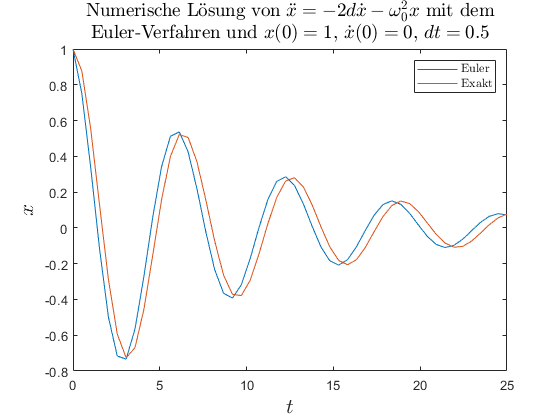

clear;
% Numerische Lösung gedämpfter Oszillator mit Euler sowie Runge-Kutta-Verfahren
% x'' = - 2*d*x' - w^2*x 

% Setup
t_0 = 0;                        % Zeitintervallgrenzen
t_max = 25;
x_0 = 1;                        % Anfangswerte
v_0 = 0;
n = 50;                         % Schrittzahl
h = (t_max - t_0) / n;          % Schrittweite
d = 0.1;                        % Dämpfung
w2 = 1;                         % Eigenfrequenz

t = linspace(t_0, t_max, n);    % Zeitdiskretisierung
x = zeros(1,n);                 % Init x-Array
v = zeros(1,n);                 % Init v-Array
x(1) = x_0;                     % Init Anfangswerte
v(1) = v_0;

% Exakte Lösung (Schwingfall):
w_d = sqrt(w2 - d^2);
x_exakt = @(t) exp(-d.*t) .* ( x_0 .* cos(w_d.*t) + (x_0.*d + v_0)./w_d .*sin(w_d.*t) );

% Rechte Seiten des DGL-Systems 1. Ordnung
% v' = -2d**v - w^2*x
% x' = v
f_v = @(x, v) -w2 * x - 2*d*v;
f_x = @(x, v) v;

% Euler zum Vergleich:
x_Euler = x;
v_Euler = v;
for i = 2:n
    v_Euler(i) = v_Euler(i-1) + h*f_v(x_Euler(i-1), v_Euler(i-1));
    x_Euler(i) = x_Euler(i-1) + h*v_Euler(i);
end

% Plot Euler
plot(t, x_Euler)
hold on;
plot(t, x_exakt(t));
%plot(t, v_Euler)
hold off;
legend('Euler', 'Exakt')
title({'Numerische L\"osung von $\ddot{x} = -2d\dot{x} - \omega_0^2 x$ mit dem','Euler-Verfahren und $x(0) = 1$, $\dot{x}(0) = 0$, $dt = 0.5$'},"Interpreter","latex","FontSize",14)
xlabel('$t$',"Interpreter","latex","FontSize",16)
ylabel('$x$',"Interpreter","latex","FontSize",16)
legend('Euler', 'Exakt',"Interpreter","latex","Location","Northeast")

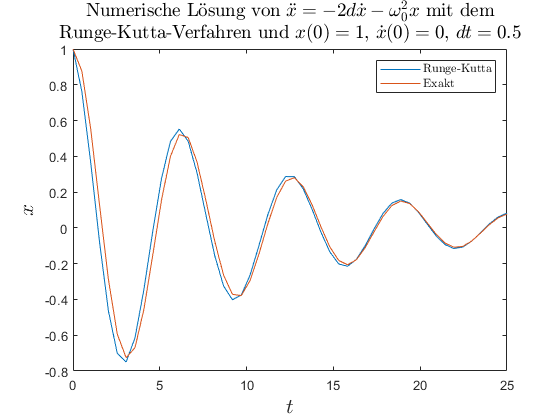



% Runge-Kutta:
for i = 2:n
    k1v = f_v(x(i-1), v(i-1));                          % Koeffizienten
    k2v = f_v(x(i-1), v(i-1) + h/2 * k1v);
    k3v = f_v(x(i-1), v(i-1) + h/2 * k2v);
    k4v = f_v(x(i-1), v(i-1) + h   * k3v);
    
    v(i) = v(i-1) + h/6 * (k1v + 2*k2v + 2*k3v + k4v);  % Schritt
    
    % Da die Rechte Seite der Gleichung für x x-unabhängig ist,
    % entspricht der Runge-Kutta-Schritt für x dem Euler-Verfahren:
    x(i) = x(i-1) + h*v(i);                             
end

% Plot Runge-Kutta
plot(t, x)
hold on;
plot(t, x_exakt(t));
%plot(t, v)
hold off;
legend('Euler', 'Exakt')
title({'Numerische L\"osung von $\ddot{x} = -2d\dot{x} - \omega_0^2 x$ mit dem','Runge-Kutta-Verfahren und $x(0) = 1$, $\dot{x}(0) = 0$, $dt =0.5$'},"Interpreter","latex","FontSize",14)
xlabel('$t$',"Interpreter","latex","FontSize",16)
ylabel('$x$',"Interpreter","latex","FontSize",16)
legend('Runge-Kutta', 'Exakt',"Interpreter","latex","Location","Northeast")

function [xVec, solVec] = fwdEuler(f, n, h, y_0, x_0, x_max) 
% Forwärts-Eulerverfahren
% f: Linke Seite der DGL, n: Zahl der Raumpunkte nach Diskretisierung
% h: Schrittweite, y_0: Anfangswert
% x_0, x_max: Intervallgrenzen
    xVec = x_0:h:x_max;
    
    solVec = zeros(1,n+1);
    solVec(1) = y_0;
    for i = 2:n+1
        solVec(i) = solVec(i-1) + h * f(solVec(i-1));
    end
end
